1.C 

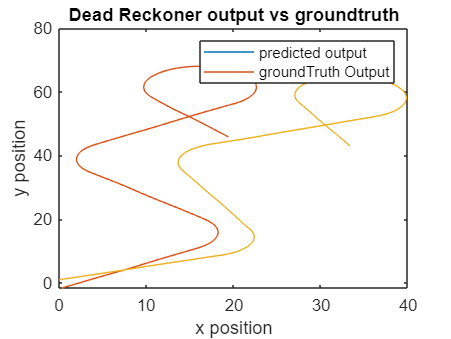

% data loaded from Kfdata file 
% t: a vector of times associated with the input signals.
% u: a matrix whose columns are the robot inputs at the times associated with t. This signal
% is the signal applied to the robot, it does not include the noise terms in v[k].
% t y: a vector of times associated with the GPS measurement.
% y: a matrix whose columns are the noisy GPS measurements taken at the times in t y.
% q groundtruth: a matrix whose columns are the robot states at the times associated the
% times in t.

%prediction step
load kfData.mat t u t_y y q_groundtruth 
n = size(t,2);
V = [0.2590 0.0010; 0.0010 0.0625];
T = 0.01;
q_hat(:,1) = [0.355;-1.59;0.682];
P = [25 0 0;0 25 0;0 0 0.154];
H = [1 0 0;0 1 0];

for k=1:1:n-1
    
    F = [1 0 -T*(u(1,k))*sin(q_hat(3,k));
        0 1 T*(u(1,k))*cos(q_hat(3,k));
        0 0 1];
    G = [T*cos(q_hat(3,k)) 0;
        T*sin(q_hat(3,k)) 0;
        0 T];
    gamma = [T*cos(q_hat(3,k)) 0;
        T*sin(q_hat(3,k)) 0;
        0 T];
    u_k = [u(1,k);u(2,k)];

    %predict
    % using non linear equation
    v = mvnrnd([0;0],V);
    q_hat(:,k+1) = [(q_hat(1,k) + T*(u(1,k) +v(1))*cos(q_hat(3,k)));
                    (q_hat(2,k) + T*(u(1,k) +v(1))*sin(q_hat(3,k)));
                    q_hat(3,k) + T*(u(2,k)+v(2))];

                 
                   
    % using linear equation                 
    P_est = F*P*transpose(F) + gamma*V*transpose(gamma);
    P = P_est;


end


hold on
plot(q_hat(1,:),q_hat(2,:))
plot(q_groundtruth(1,:),q_groundtruth(2,:))
legend('predicted output', 'groundTruth Output')
title('Dead Reckoner output vs groundtruth')
xlabel('x position') 
ylabel('y position')
hold off